# Model Fidelity: Converter (average, ideal switching, detailed switching, subcycle averaging)

Copyright 2023-2024 The MathWorks, Inc.

## Literature Review / References

[1]    [https://www.mathworks.com/help/sps/ug/power-converter-model-fidelity-comparison.html](https://nl.mathworks.com/help/sps/ug/power-converter-model-fidelity-comparison.html) 

[2]    [https://mathworks.com/help/sps/ug/manage-model-fidelity-using-variants.html](https://nl.mathworks.com/help/sps/ug/manage-model-fidelity-using-variants.html) 

## Overview

This script analyses the simulation execution time of models using various fidelity levels [2] of a converter and control systems.

**Use-Cases**: 

**                                                                                             Contains Harmonics         Application Domain**

- **Low (Average Switch, Mod Wave)                       No                                      Control Design on PC**

- **Medium (Average Switch, Averaged Pulses)     Yes                                     HiL running models on CPU**

- **High   (Ideal Switch,  Pulses)                               Yes                                     Harmonic Analysis on PC**

## Approach

- Select shipping examples containing the different types of converter switching fidelity

- Adjust the shipping examples as needed to demonstrate different ways of "speeding up" through model fidelity, taking into account the use-cases

- Illustrate accuracy vs. execution time

All steps coded in this Live-Script can be applied also interactively with the User Interface (UI) in Simulink.  They are coded here for a better reproducibility. 

### Step 2: Open the example model [2]                 

Path = pwd;

example = 'simscapeelectrical/FidelityVariantsExample';
openExample(example)
mdl = bdroot;

cd(Path);

Make the simulation time longer, to distinguish better between the overhead of code-gen / build vs. execution time.

set_param(mdl,'StopTime','1');  

Return simulation outputs as a single Simulink.SimulationOutput object containing Execution Time Information.

set_param(mdl,'ReturnWorkspaceOutputs',true);

### Step 3: Choose the Use Case

set_param(mdl,'FastRestart','off');
UseCase = 3;
switch UseCase
    case 1
        fidelity = FidelityVariantsEnum.Low;
        Ts = 1e-4;
    case 2
        fidelity = FidelityVariantsEnum.Medium;
        Ts = 5e-5;
    case 3
        fidelity = FidelityVariantsEnum.High;
        Ts = 1e-5;
end


### Step 4: Choose the Simulation Mode

set_param(mdl,'FastRestart','off');
simMode ="accelerator";
set_param(mdl,'SimulationMode',simMode);
% 'FastRestart'only works for normal and accelerator mode
if strcmp(get_param(mdl,'SimulationMode'),'normal') || strcmp(get_param(mdl,'SimulationMode'),'accelerator')
    set_param(mdl,'FastRestart','on');
end
set_param(mdl,'SimulationCommand','Update')

### Step 5: Run the Simulation

Run the Simulation multiple times, so that the build and execution times are better visible and to see the variation in simulation times for each mode.

Observation: the simulation execution time in one mode, e.g. normal with fast restart, ran 10 times after each other, can vary quite a lot, e.g. between 2.6 and 3.8 seconds.

The PC is not a real-time hardware, therefore such variation in execution times can be expected. 

NumIterations = 10;
ExecutionTimes = zeros(1,NumIterations);
MD = Simulink.SimulationMetadata.empty;
for ii = 1:NumIterations
    sim_result = sim(mdl);
    MD = [MD sim_result.getSimulationMetadata];
    ExecutionTimes(ii) = MD(ii).TimingInfo.ExecutionElapsedWallTime;
end
ExecutionTimes

ExecutionTimes =     0.1638    0.2157    0.3467    0.2181    0.2013    0.2083    0.2235    0.2134    0.2041    0.2148


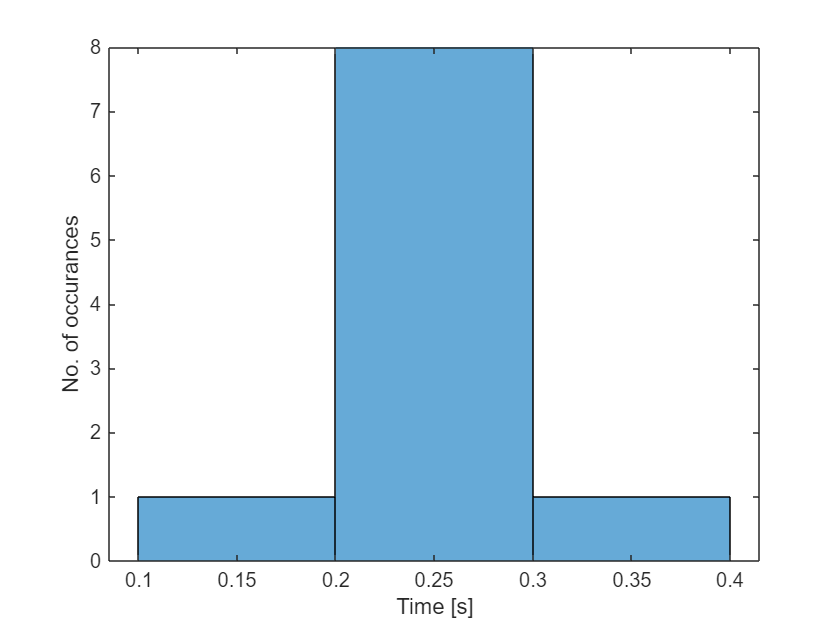

histogram(ExecutionTimes); xlabel('Time [s]'); ylabel('No. of occurances');

Observation: the "Elapsed Time" using Tic Toc is not very useful, since it varies quite a lot, it seems to depend on other active processes on the PC.

The ExecutionTimes(ii) = MD.TimingInfo.ExecutionElapsedWallTime seems to be a better indication of actual execution time. 

Below are the documented execution times on my PC (Base Speed 2.11 GHz, 4x cores)

**Use Case **                                                                         **Normal                           Accelerator         **

- **Low (Average Switch, Mod Wave)                    ~ 1.25 sec                      ~ 1.0 sec**

- **Medium (Average Switch, Averaged Pulses)   ~ 2,75 sec                      ~ 2,1 sec**

- **High   (Ideal Switch,  Pulses)                             ~ 7.0 sec                        ~ 6.5 sec                          **